clear all;
close all;

m=200;n=200;J=5/2;
theta_list=[0:pi/(m-1):pi];
phi_list=[0:2*pi/(n-1):2*pi];

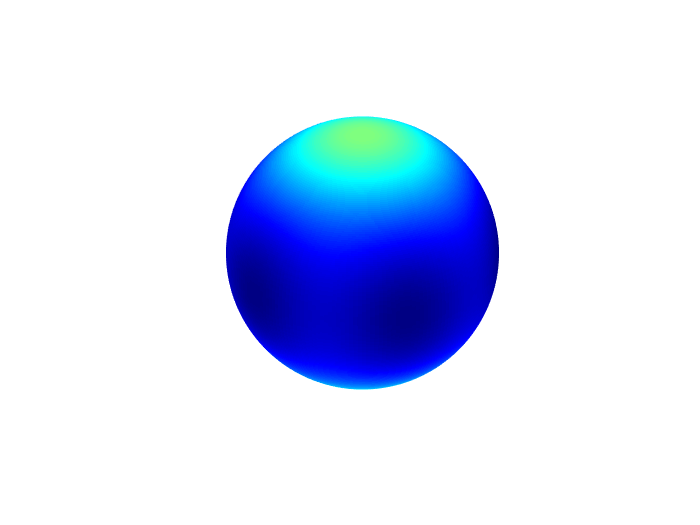

state=[1,0,0,0,0,1]'./sqrt(2);
for i=1:length(theta_list)
    for j=1:length(phi_list)
        phi=phi_list(j);
        theta=theta_list(i);
        wigner_result(i,j)=abs(spin_coherent(theta,phi)'*state)^2;
    end
end
wigner_plot_only_fun(wigner_result);

function wigner_plot_only_fun(wigner_result)
    [m,n]=size(wigner_result);
    theta_list=[0:pi/(m-1):pi];
    phi_list=[0:2*pi/(n-1):2*pi];
   
    %f1=figure;
    theta_list=pi/2-theta_list;
    [theta2,phi2]=meshgrid(theta_list,phi_list);
    [x,y,z]=sph2cart(phi2,theta2,1);
    surf=mesh(x,y,z,real(wigner_result'));
    xlim([-1 1]);
    zlim([-1 1]);
    ylim([-1 1]);
    caxis([0 1])
    %caxis([-1 1]);
    xlabel('x');
    ylabel('y');
    %view([0 90]);
    %set(f1,"Visible","On");
    daspect([1 1 1]);
    %axis equal;
    set(surf,"LineStyle","none", "FaceColor","texturemap",...
        "FaceLighting","gouraud");
    colorbar('off');
    box off;
    axis off;
    colormap('jet');
    
    %cMap=getPyPlot_cMap('coolwarm');
    %colormap(cMap);
end

function state=spin_coherent(theta,phi)
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');
polar=[1 0 0 0 0 0]';
state1=ham_evolve(sigmay,polar,theta);
state=ham_evolve(sigmaz,state1,phi);
end

function final=ham_evolve(ham,initial,time)
try
    final=expm(-1i*ham*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end